**MEC4047F Assignment 1 - Analytical Solution**

(a) Draw the Free Body Diagram for the sprung components of the washing machine and determine the differential equation of motion. The ”sprung components” include the rotating drum, the shroud which contains the water and the motor which is rigidly coupled to the shroud. Following the approach presented in class where we assume a harmonic steady-state displacement response of the form xp(t) = X1 cos(ωt) + X2 sin(ωt), determine the dynamic magnification ratio and the phase angle. Plot the phase angle as a function of frequency ratio

% Physical parameters

m = 54

m = 54

c = 320

c = 320

k = 26000

k = 26000


m_0 = 5.5

m_0 = 5.5000

e = 0.450/2

e = 0.2250


m = m + m_0

m = 59.5000


% Derived system values

zeta = c/(2*sqrt(m*k))

zeta = 0.1286

omega_n = sqrt(k/m)

omega_n = 20.9039

omega_d = omega_n*sqrt(1-zeta^2)

omega_d = 20.7303

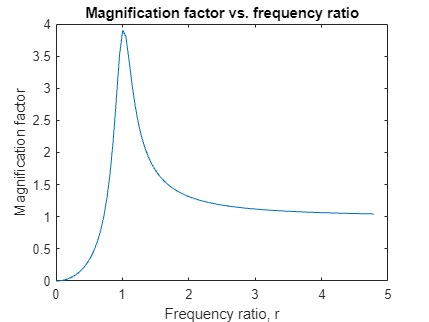


% Plot output of magnification factor and phase angle

omega = 0:1:100;
r = (omega/omega_n);

mag_fact = (r).^2./sqrt((1-(r).^2).^2 + (2*zeta*r).^2);
phi = atan(2*zeta.*(r)./(1-((r).^2)));

for i=1:length(phi)
    if phi(i) < 0
        phi(i) = phi(i) + pi;
    end
end

plot(r, mag_fact), title('Magnification factor vs. frequency ratio'), xlabel('Frequency ratio, r'), ylabel('Magnification factor')

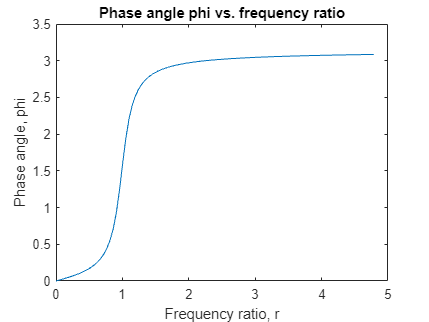

plot(r, phi), title('Phase angle phi vs. frequency ratio'), xlabel('Frequency ratio, r'), ylabel('Phase angle, phi')

(b) Assuming zero initial displacement and velocity, find the analytical solution for the total vertical displacement response (i.e. transient and steady state). Plot the the total displacement response and establish how quickly (in natural periods) the transient dies away, for drum speeds of 400 rpm, 800 rpm and 1200 rpm.

% Initial conditions

x_0 = 0

x_0 = 0

x_0_dot = 0

x_0_dot = 0


% Solve for forced response

omega = [400*0.1047198, 800*0.1047198, 1200*0.1047198]

omega =    41.8879   83.7758  125.6638



f_0 = m_0*e*(omega.^2)

f_0 = 1.0e+04 *

    0.2171    0.8685    1.9542



r = omega/omega_n

r =     2.0038    4.0077    6.0115



psi = atan(2*zeta.*r./(1-(r.^2)))

psi =    -0.1693   -0.0684   -0.0440



X_mag = f_0./sqrt((k-m.*omega.^2).^2 + c^2.*omega.^2)

X_mag =     0.0273    0.0221    0.0214


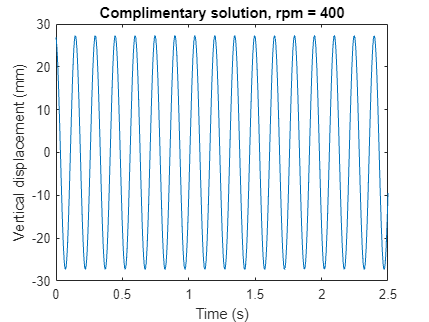


x = linspace(0,2.5,1000);

x_c1 = f_0(1)/sqrt((k-m*omega(1)^2)^2 + c^2*omega(1)^2)*cos(omega(1)*x - psi(1));
plot(x, x_c1*1000), title('Complimentary solution, rpm = 400'), xlabel('Time (s)'), ylabel('Vertical displacement (mm)')

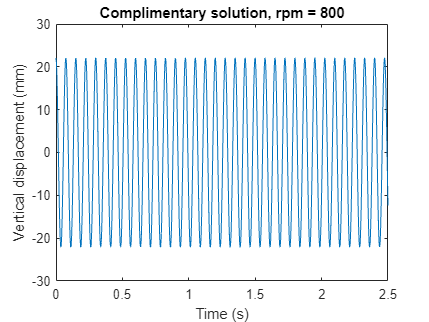


x_c2 = f_0(2)/sqrt((k-m*omega(2)^2)^2 + c^2*omega(2)^2)*cos(omega(2)*x - psi(2));
plot(x, x_c2*1000), title('Complimentary solution, rpm = 800'), xlabel('Time (s)'), ylabel('Vertical displacement (mm)')

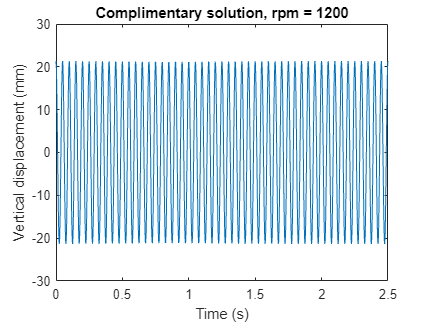


x_c3 = f_0(3)/sqrt((k-m*omega(3)^2)^2 + c^2*omega(3)^2)*cos(omega(3)*x - psi(3));
plot(x, x_c3*1000), title('Complimentary solution, rpm = 1200'), xlabel('Time (s)'), ylabel('Vertical displacement (mm)')


% Solve for transient response

A_3 = -X_mag.*cos(-psi)

A_3 =    -0.0269   -0.0221   -0.0213


A_4 = (omega.*X_mag.*sin(-psi) + zeta*omega_n.*A_3)./omega_d

A_4 =     0.0058    0.0032    0.0029



transient_exponential = -zeta*omega_n

transient_exponential = -2.6891

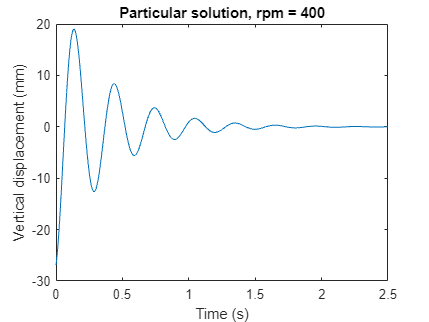


x_p1 = (A_3(1)*cos(omega_d*x) + A_4(1)*sin(omega_d*x)).*exp(-zeta*omega_n*x);
plot(x, x_p1*1000), title('Particular solution, rpm = 400'), xlabel('Time (s)'), ylabel('Vertical displacement (mm)')

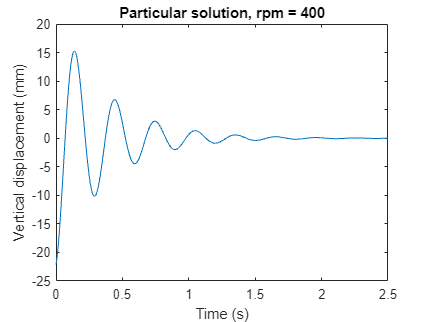

x_p2 = (A_3(2)*cos(omega_d*x) + A_4(2)*sin(omega_d*x)).*exp(-zeta*omega_n*x);
plot(x, x_p2*1000), title('Particular solution, rpm = 400'), xlabel('Time (s)'), ylabel('Vertical displacement (mm)')

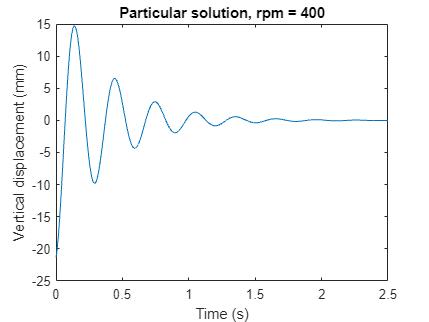

x_p3 = (A_3(3)*cos(omega_d*x) + A_4(3)*sin(omega_d*x)).*exp(-zeta*omega_n*x);
plot(x, x_p3*1000), title('Particular solution, rpm = 400'), xlabel('Time (s)'), ylabel('Vertical displacement (mm)')

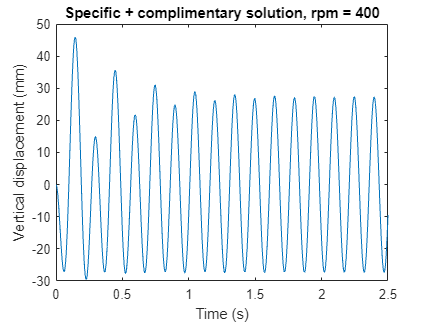

% Plot combined responses

plot(x, (x_p1 + x_c1)*1000), title('Specific + complimentary solution, rpm = 400'), xlabel('Time (s)'), ylabel('Vertical displacement (mm)')

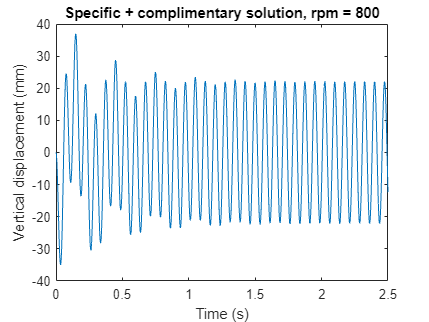

plot(x, (x_p2 + x_c2)*1000), title('Specific + complimentary solution, rpm = 800'), xlabel('Time (s)'), ylabel('Vertical displacement (mm)')

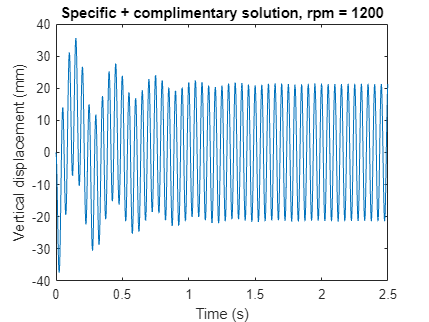

plot(x, (x_p3 + x_c3)*1000), title('Specific + complimentary solution, rpm = 1200'), xlabel('Time (s)'), ylabel('Vertical displacement (mm)')

(c) Derive a relationship for the total force exerted on the floor by the drum suspension (springs and dampers). You should plot the magnitude of force as a function of frequency ratio. 

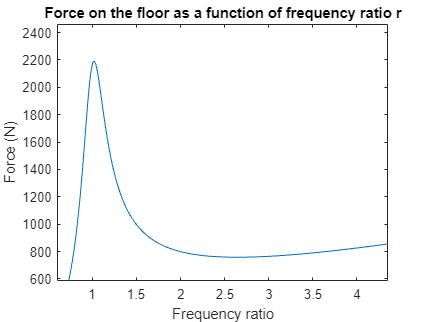

% Both function of displacement of washing machine (spring - vertical
% displacement, damper - vertical velocity.

r = linspace(0, 5, 1000);

% Let A be amplitude of vertical movement, and B be amplitude of vertical
% velocity
% Explain this shit in the report, future me, cause i sure aint
% Hope you dont lose this random piece of paper lmao

A = (m_0*e/m)*(r.^2./sqrt((1-r.^2).^2+(2*zeta.*r).^2))*k;
B = -(omega_n*r)*(m_0*e/m).*(r.^2./sqrt((1-r.^2).^2+(2*zeta.*r).^2))*c;

C = sqrt(A.^2 + B.^2);

plot(r, C), title("Force on the floor as a function of frequency ratio r"), xlabel('Frequency ratio'), ylabel('Force (N)')